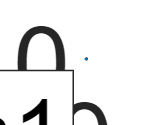

clear all;
%close all;
F = 5/2;
sigmax = spinOp(F,'x');
sigmay = spinOp(F,'y');
sigmaz = spinOp(F,'z');
initial = zeros(2*F+1,1);
initial(1) = 1;
%initial=spin_coherent(pi/2,pi/2);

timelist = [0:0.01:4].*pi;
%timelist = pi/2;
ham = 1*sigmax-1*sigmax^2+0*sigmaz;
%ham=3.7944*sigmax+0.46524*sigmax^2;
%ham=sigmay^2;

for i = 1:length(timelist)
    time = timelist(i);
    finalstate(i,:) = ham_evolve(ham, ...
        initial,time);
end

finalstate = (conj(finalstate).*finalstate)';

figure;
for j = 1:1
    plot(timelist/pi,(finalstate(j,:)), ...
        'LineWidth',2);
    hold on;
end
ylim([0 1]);
legend;
%set(gcf,'visible','on')
set(gca,'fontsize',35)

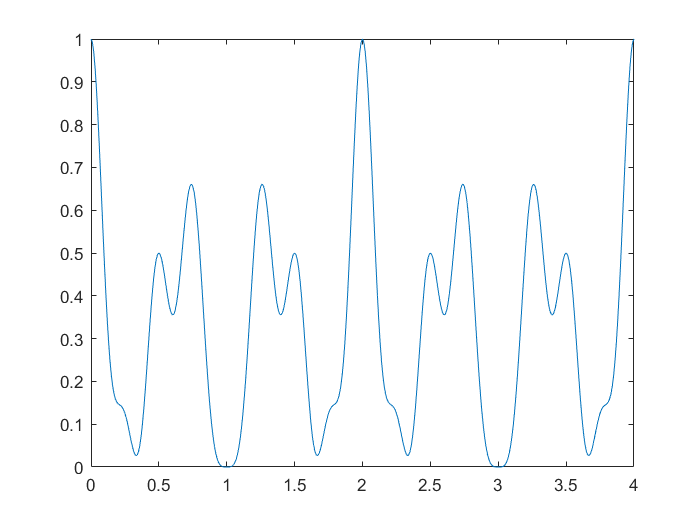

%phase = (finalstate(1,:)-finalstate(6,:))...
%    ./(finalstate(1,:)+finalstate(6,:));

phase = (finalstate(1,:));
figure;
plot(timelist/pi,phase);
ylim([0 1]);
set(gcf,'Visible','on');

function final = ham_evolve(ham,initial,time)
try
    final = expm(-1i*ham*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end

function state = spin_coherent(theta,phi)
sigmay = spinOp(5/2,'y');
sigmaz = spinOp(5/2,'z');
polar = [1 0 0 0 0 0]';
state1 = ham_evolve(sigmay,polar,theta);
state = ham_evolve(sigmaz,state1,phi);
end